% Workflow:
% 1. read the titles of a LIF file
% 2. read a 3D image
% 3. preprocessing
% 4. scale E and S to 50
% 5. set up tuning
% 6. tuning parameters
% 7. attenuation correction (exponential)
% 8. check and save

% 1. read the titles of a LIF file
filename = strrep('D:\Nick\3D HnE\20240125 human SnE staining 2.lif', '\', '/');
omit_suffix = 'tile scan';
read_image_titles(filename, omit_suffix);

Image titles in D:/Nick/3D HnE/20240125 human SnE staining 2.lif:
1. normal breast
145. breast cancer/breast cancer tile merge
290. normal appendix/appendix tile merge
291. normal lung too little eosin


% 2. read a 3D image
image_index = 145;
E_S_channel = [1, 2];
start_plane = 1; % <= 1: from first plane
end_plane = 500; % > number of Z planes: until last plane
omit_last_plane = false; % additionally deduct one plane
image = read_image(filename, image_index, E_S_channel, start_plane, end_plane, omit_last_plane);

Progress: 100%


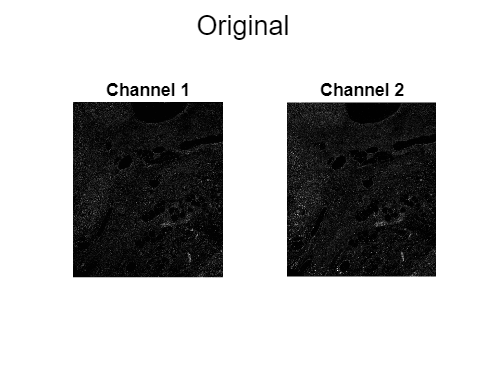

display_first_plane(image, 'Original');

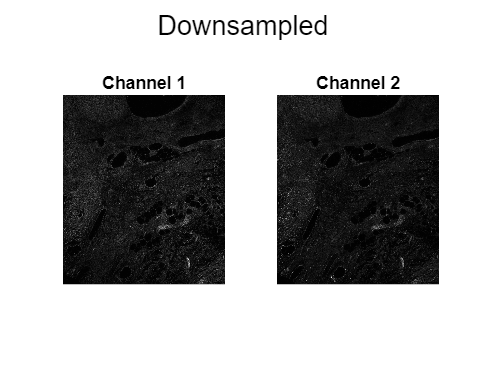

% 3.1 downsample XY
downsample_XY_factor = 2;
d_image = downsample_image(image, downsample_XY_factor);
display_first_plane(d_image, 'Downsampled');

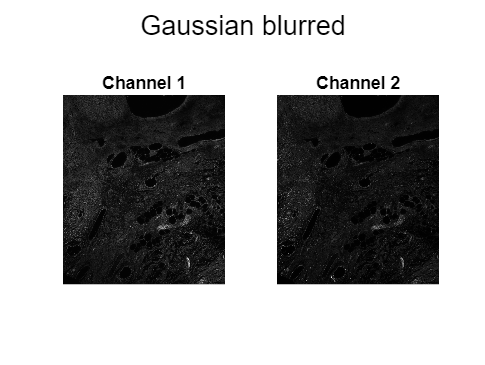

% 3.2 gaussian blur 3D
sigma_xy = 1;
sigma_z = 1;
g_image = gaussian_blur_3d(d_image, sigma_xy, sigma_z);
display_first_plane(g_image, 'Gaussian blurred');

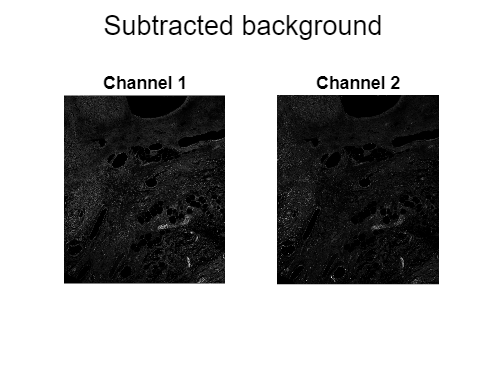

% 3.3 subtract background (mean * 0.2)
background_level = 0.2;
sb_image = subtract_background(g_image, background_level);
display_first_plane(sb_image, 'Subtracted background');

% 4. scale E and S to 50
image = sb_image;
interval = 10;
analyze_image(image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0.00	151.81	13.45	0.00	248.35	16.03


scale_target = 50;
image = scale_to_50(image, interval, scale_target);

Max Mean E: 13.45
Max Mean S: 16.03
Scaling Factor E: 3.7180
Scaling Factor S: 3.1196


analyze_image(image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0.00	564.43	50.00	0.00	774.77	50.00


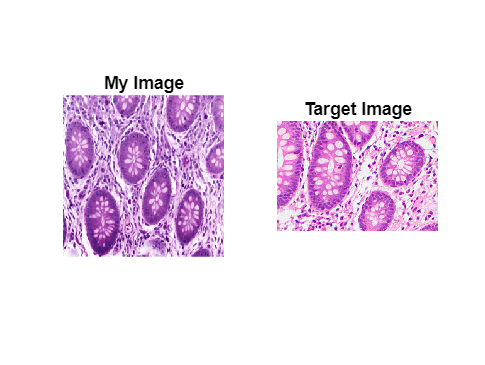

% 5. show initial image and target image
brightest_plane = load_brightest_plane(image, interval);

% default_parameters
E_to_S_base = 0;
S_to_E_base = 0;
scale_E_base = 1;
scale_S_base = 1;
default_parameters = [0, 0, 1, 1];

% display initial and target image
initial_image = convert_RGB_plane(brightest_plane, default_parameters);
target_image = im2double(imread('D:/Nick/3D HnE/20240413 colour transfer/colon_example_4.png'));
display_two_images(initial_image, target_image);

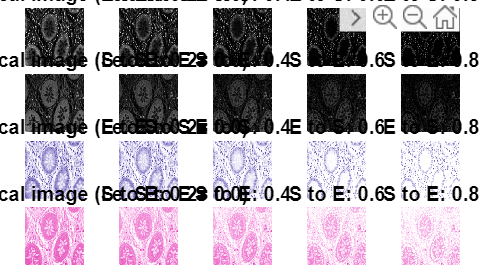

% 6.1 try crosstalk parameters
base_parameters = [0, 0, 1, 1];
E_to_S_try = [0, 0.2, 0.4, 0.6, 0.8];
S_to_E_try = [0, 0.2, 0.4, 0.6, 0.8];
crosstalk_try = [E_to_S_try; S_to_E_try];
zoom_factor = 1.5;
display_crosstalk_try(brightest_plane, base_parameters, crosstalk_try, zoom_factor);

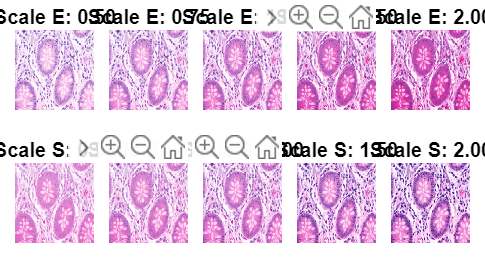

% 6.2 try scale parameters
base_parameters = [0.6, 0.3, 1, 1];
scale_E_try = [0.5, 0.75, 1, 1.5, 2];
scale_S_try = [0.5, 0.75, 1, 1.5, 2];
scale_parameters = [scale_E_try; scale_S_try];
zoom_factor = 1.5;
display_scale_try(brightest_plane, base_parameters, scale_parameters, zoom_factor);

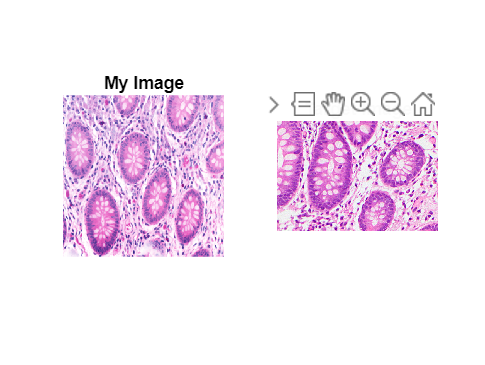

% 6.3 pick parameters
picked_parameters = [0.6, 0.3, 1, 1.2];
final_image = convert_RGB_plane(brightest_plane, picked_parameters);
display_two_images(final_image, target_image);

% 6.4 scale stack with picked parameters
spp_image = scale_stack(image, picked_parameters);
analyze_image(spp_image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0.00	262.85	35.35	0.00	308.74	30.83
11	0.00	207.33	33.92	0.00	251.70	25.71
21	0.00	222.34	30.87	0.00	199.84	22.04
31	0.00	176.73	28.35	0.00	221.33	19.24
41	0.00	211.81	26.58	0.00	171.35	17.09
51	0.00	233.98	24.65	0.00	149.37	15.44
61	0.00	189.62	22.70	0.00	140.36	13.93



Decay Coefficients:
E channel: exponential_E = -7.56e-03
S channel: exponential_S = -1.31e-02


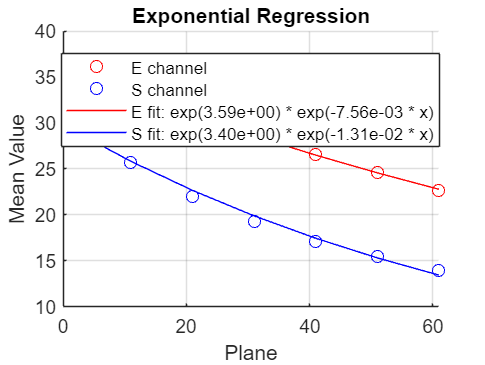

% 7. attenuation correction (exponential)
[exponential_E, exponential_S] = exponential_regression(spp_image, interval);

ac_image = attenuation_correction(spp_image, exponential_E, exponential_S);
analyze_image(ac_image, interval);

Plane	Min E	Max E	Avg E	Min S	Max S	Avg S
1	0.00	262.85	35.35	0.00	308.74	30.83
11	0.00	223.61	36.58	0.00	286.81	29.29
21	0.00	258.63	35.91	0.00	259.48	28.61
31	0.00	221.73	35.57	0.00	327.46	28.47
41	0.00	286.61	35.96	0.00	288.88	28.81
51	0.00	341.46	35.98	0.00	286.95	29.66
61	0.00	298.46	35.73	0.00	307.25	30.50


% 8.1 check image
z_index = [1, 101, 201, 401]; 
display_image(ac_image, z_index);

% 8.2 save image
filepath = 'D:/Nick/3D HnE/20240413 colour transfer/colon for figure.tiff';
chunk_size = 201;
save_tiff(ac_image, chunk_size, filepath);